plot 그리기

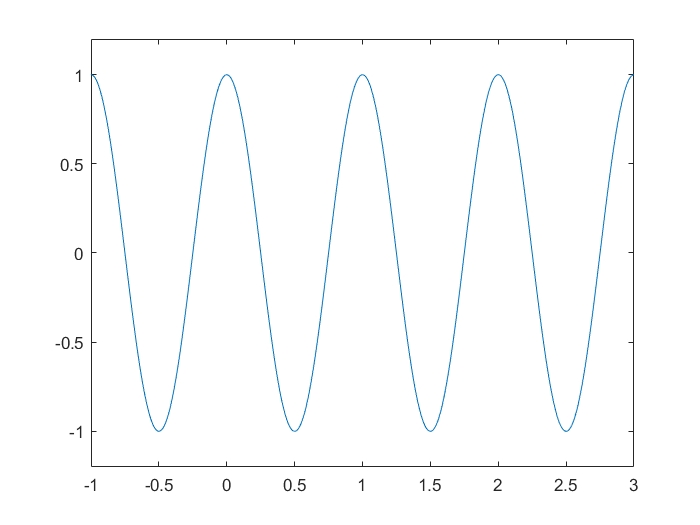

t=-1:0.01:3; % 파형의 시간축 
f0=1; % 주파수
A=1; % 진폭
phi=0; % 위상
x=A*cos(2*pi*f0*t+phi); % 위상이 0인 정현파
plot(t,x)
axis([-1 3 -1.2 1.2]); % x축(-1∼3) y축(-1.2∼1.2)

one plot several graph ver 1

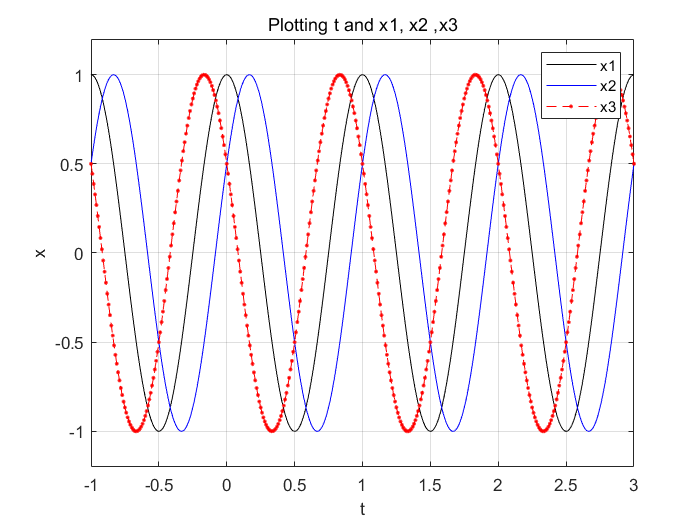

t=-1:0.01:3;
f0=1;
A=1;
phi=[0 -(pi/3) pi/3];
x1=A*cos(2*pi*f0*t+phi(1)); % 위상이 0인 정현파
x2=A*cos(2*pi*f0*t+phi(2)); % 위상이 -pi/3인 정현파
x3=A*cos(2*pi*f0*t+phi(3)); % 위상이 pi/3인 정현파
figure % 그래프 명시(label, title 사용시 분리 가능성 O)
plot(t,x1,'k',t,x2,'b-',t,x3,'r--.')
axis([-1 3 -1.2 1.2]);
legend('x1','x2','x3'); % 범례
xlabel('t'); % x축 이름
ylabel('x'); % y축 이름
title('Plotting t and x1, x2 ,x3'); % 제목
grid on % 범위 점선

one plot several graph ver 2

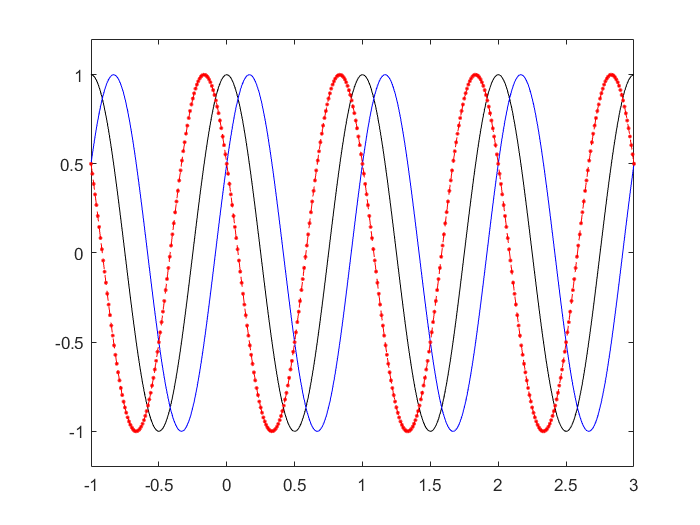

t=-1:0.01:3;
f0=1;
A=1;
phi=[0 -(pi/3) pi/3];
plot(t,x1,'k'); axis([-1 3 -1.2*A 1.2*A]);
hold on 
plot(t,x2,'b-'); 
plot(t,x3,'r--.'); 

several plot several graph

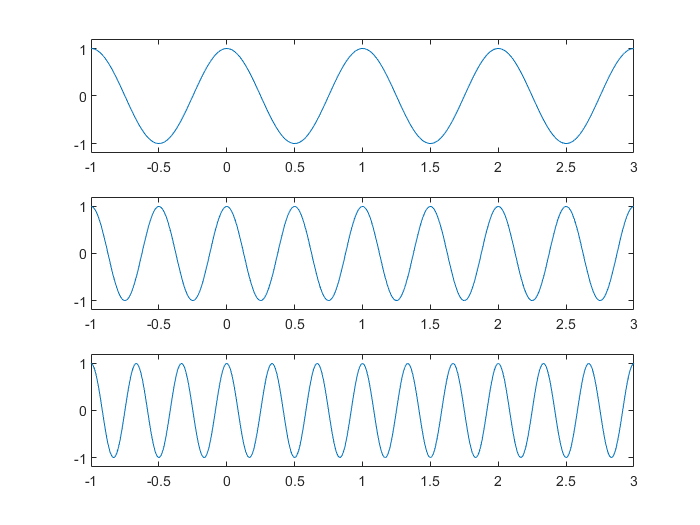

t=-1:0.01:3;
A=1;
f0=[1 2 3];
x1=A*cos(2*pi*f0(1)*t); % 주파수가 1인 정현파
x2=A*cos(2*pi*f0(2)*t); % 주파수가 2인 정현파
x3=A*cos(2*pi*f0(3)*t); % 주파수가 3인 정현파
subplot(3,1,1)
plot(t,x1); axis([-1 3 -1.2 1.2]);
subplot(312) % ,로 분리하지 않아도 됨
plot(t,x2); axis([-1 3 -1.2 1.2]);
subplot(3,1,3)
plot(t,x3); axis([-1 3 -1.2 1.2]);